# PROGETTO 1

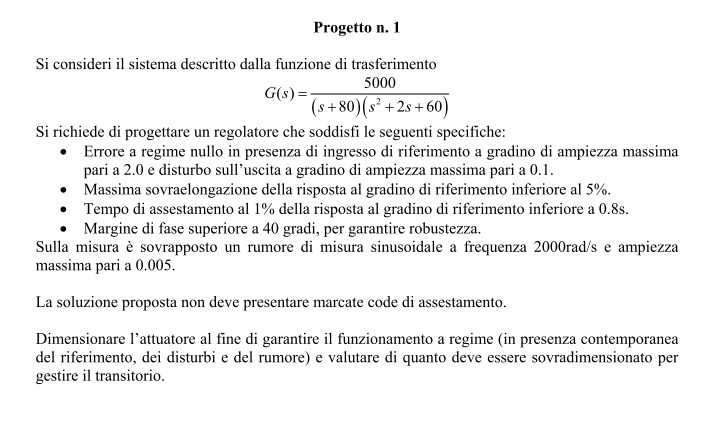

Ambrosini Matteo

Buriani Gioele

Galletti Vittorio

### ANALISI DEL PLANT:

Inizialmente, si può definire la funzione di partenza G(s) che descrive il plant del sistema.

s=tf('s');
G=5000/((s+80)*(s^2+2*s+60))

G =
 
                 
             5000
                 
  --------------------------
                            
  s^3 + 82 s^2 + 220 s      
                            
                      + 4800
                            
 
Continuous-time transfer function.



Si può notare la presenza di una coppia di poli complessi coniugati con le seguenti proprietà:

omegan_G=sqrt(60)

omegan_G = 7.7460

delta_G=1/omegan_G

delta_G = 0.1291

I valori di questa coppia sono solamente nominali, per cui non si possono basare su di essi ragionamenti riguardanti un'eventuale cancellazione esatta.

Le informazioni ricavate garantiscono la presenza di un picco di risonanza in corrispondenza di omegan=7.75r/s (valore che può leggermente variare al fronte delle incertezze). Ciò si può verificare tracciando il diagramma di Bode di G(s).

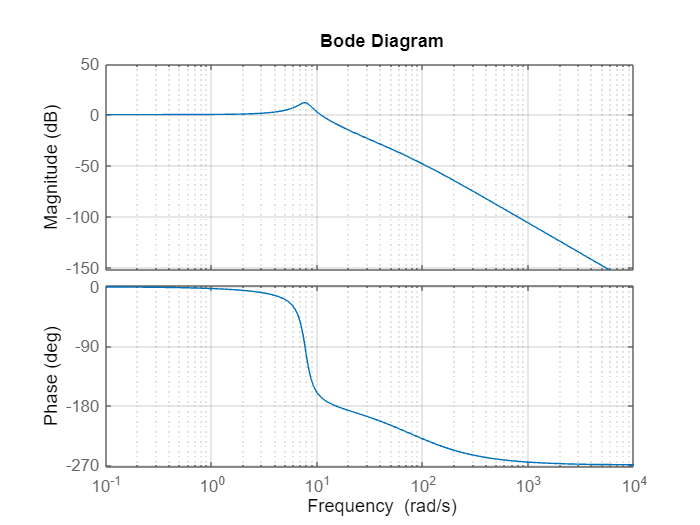

bode(G)
grid

Il sistema presenta inoltre un tempo di assestamento all'1% pari a 4.6 secondi.

Ta_G=4.6/(delta_G*omegan_G)

Ta_G = 4.6000

Si può verificare facendo lo step di G(s).

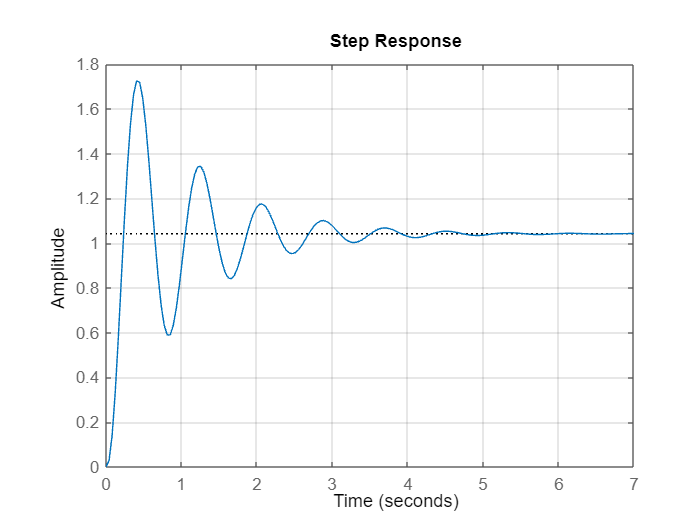

step(G)
grid

Definiamo anche preventivamente l'opzione per imporre l'ampiezza dello step del segnale di riferimento.

opt=stepDataOptions('StepAmplitude',2);

### PROGETTO REGOLATORE STATICO:

Per quanto riguarda le specifiche statiche, dovendo avere errore nullo rispetto ad un ingresso di riferimento e ad un disturbo di misura entrambi a gradino, per il "Principio del modello interno" si possono inseguire/attenuare a regime perfettamente entrambi progettando un polo nell'origine nel regolatore statico Rs(s).

Rs=1/s;

Si può ora definire la funzione G estesa Ge(s):

Ge=G*Rs

Ge =
 
                 
             5000
                 
  --------------------------
                            
  s^4 + 82 s^3 + 220 s^2    
                            
                    + 4800 s
                            
 
Continuous-time transfer function.



Si rivaluta la risposta a gradino del sistema.

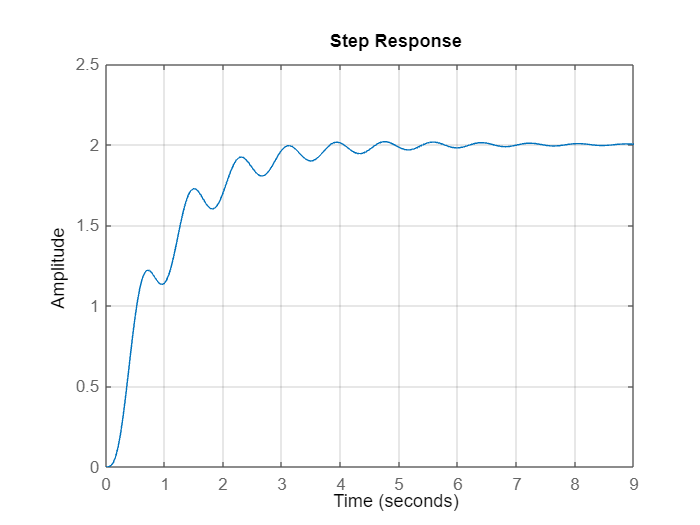

step(Ge/(1+Ge),opt)
grid

### DEDUZIONE DELLE SPECIFICHE DINAMICHE:

Per quanto riguarda le specifiche dinamiche, è richiesta una massima sovraelongazione percentuale S%<5% (in termini pratici corrisponde all'assenza di sovraelongazione) e un tempo di assestamento all'1% Ta=0.8sec.

Da queste specifiche dinamiche si possono dedurre i valori di delta e omegan.

delta_0=0.75;
omegan_0=4.6/(delta_0*0.8);

Si usano le trasformazioni approssimate per ricavare le specifiche frequenziali partendo da quelle dinamiche.

Mf_0=100*delta_0

Mf_0 = 75

omegac_0=omegan_0

omegac_0 = 7.6667

È quindi richiesto un attraversamento a 7.67r/s con margine di fase pari a 75°.

Si può vedere che che la pulsazione di attraversamento desiderata omegac_0=7.67r/s è molto vicina alla pulsazione omegan_G=7.75r/s per la quale si presenta il picco di risonananza nel plant.

Questa coincidenza rappresenta una problematica per il progetto. Infatti, in corrispondenza della coppia di poli c.c. si ha forte pendenza in termini di fase il che comporta bassa robustezza nel gestire il margine di fase in presenza di eventuali incertezze.

Risulta inoltre critico attraversare in corrispondenza del picco in quanto potrebbero esserci problematiche di doppio o triplo attraversamento.

### POSSIBILI SCELTE DI PROGETTAZIONE:

Ci sono due possibili soluzioni per risolvere la problematica appena descritta:

- La prima soluzione prevede l'imposizione dell'attraversamento a frequenze più alte rispetto a omegac. Ciò fornirebbe un sistema più veloce di quello richiesto, ma ci si troverebbe in uno scenario B "pesante" per cui sarebbe necessario un sforzo di controllo molto alto.  In questo caso bisognerebbe usare un prefiltro per ovviare al problema.

- La seconda soluzione prevede l'imposizione dell'attraversamento a frequenze più basse rispetto a omegac. Ciò fornirebbe un sistema in condizioni più favorevoli (scenario A), ma più lento rispetto a quanto richiesto dalle specifiche dinamiche. In questo caso bisognerebbe usare un regolatore in feed-forward per velocizzare il sistema e ovviare al problema.

### SCENARIO 1:

Si prova ad adottare inizialmente la prima soluzione.

Imporre l'attraversamento nell'intorno di omegan_G=7.75r/s crea problematiche di robustezze sia in termini di ampiezza (c'è un picco di risonanza), sia in termine di fase (la fase crolla in maniera molto ripida).

Si decide quindi di considerare una pulsazione di attraversamento omegac_1 più bassa possibile, ma che esca dalla "zona critica" di ampiezza e fase.

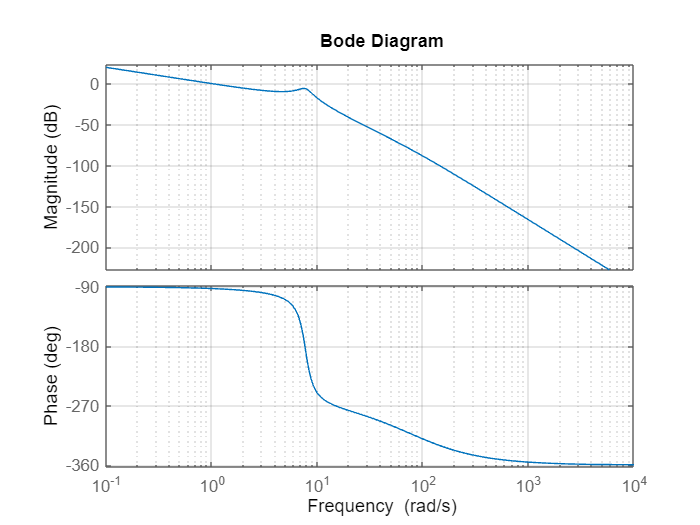

bode(Ge)
grid

Studiando il bode di Ge(s) si può verificare che la scelta di omegac_1=11 risulta sensata rispetto ai ragionamenti fatti in precedenza.

omegac_1=11

omegac_1 = 11

L'opzione più conveniente sembrerebbbe l'implementazione di un regolatore PID sfruttando il polo nell'origine del regolatore statico già implementato.

Sapendo già di dover posizionare un polo di fisica realizzabilità a una pulsazione 10 volte maggiore rispetto a omegac_1, si decide di fare questa operazione in anticipo in modo da poter valutare preventivamente l'effetto del polo (seppur minimo) in termini di ampiezza e fase alla pulsazione di attraversamento omegac_1.

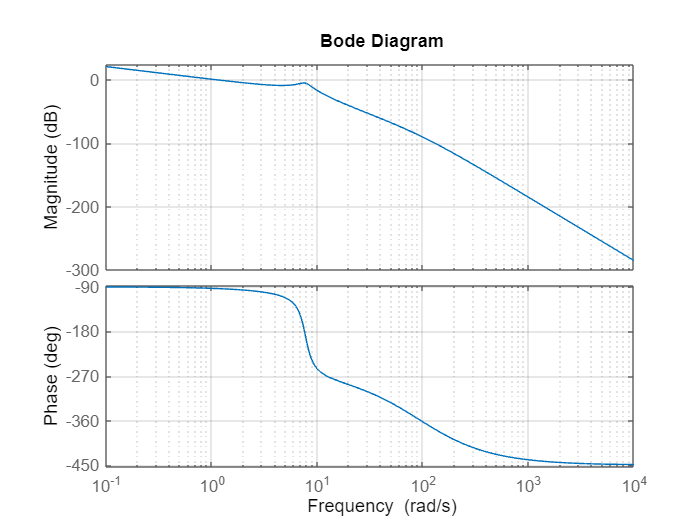

taup_1=1/(10*omegac_1);
Rd_1=1/(1+taup_1*s);
bode(Ge*Rd_1)
grid

In corrispondenza di 11.0r/s l'ampiezza risulta uguale a -21.2dB e la fase pari a -264°. È quindi necessaria un'amplificazione di 21.2dB e un'anticipazione di 159°(=264-180+75).

Per la scelta degli zeri del regolatore PID, si decide di usare due zeri con la stessa costante tauz_1.

Si trova inizialmente il valore di rho necessario per fornire l'anticipazione necessaria.

rho_1=tand(159/2);

Si può già notare una possibile anomalia in quanto ciascuno zero dovrebbe anticipare di circa 80° che risulta praticamente impossibile da un punto di vista pratico. Per il momento ignoriamo questo problema.

Dal valore di rho è possibile ricavare la costante di tempo tauz che caratterizzerà i due zeri.

tauz_1=rho_1/omegac_1;

Si può ora definire il regolatore dinamico Rd_1.

Rd_1=(1+tauz_1*s)^2/(1+taup_1*s);

È ora necessaria la scelta del guadagno statico mu_1 per imporre l'attraversamento a omegac_1.

Si studia il diagramma di Bode del sistema G esteso moltiplicato per il regolatore dinamico appena progettato.

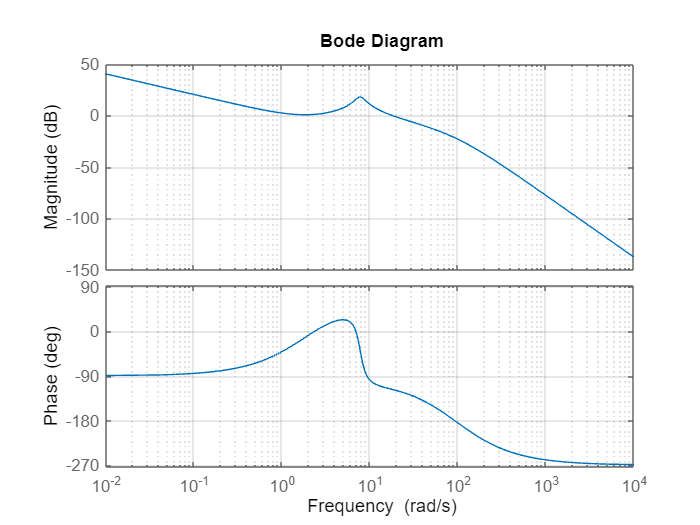

bode(Rd_1*Ge)
grid

Dallo studio del diagramma si deduce un'attenuazione necessaria di 8.33dB. Si può quindi ricavare il valore di mu.

mu_1=10^(-8.33/20)

mu_1 = 0.3833

Si può ora definire il regolatore R_1 finale.

R_1=mu_1*Rs*Rd_1

R_1 =
 
                            
  0.09221 s^2 + 0.376 s     
                            
                    + 0.3833
                            
  --------------------------
                       
       0.009091 s^2 + s
                       
 
Continuous-time transfer function.



Si valuta il margin di L(s) per verificare che le specifiche siano state implementate correttamente.

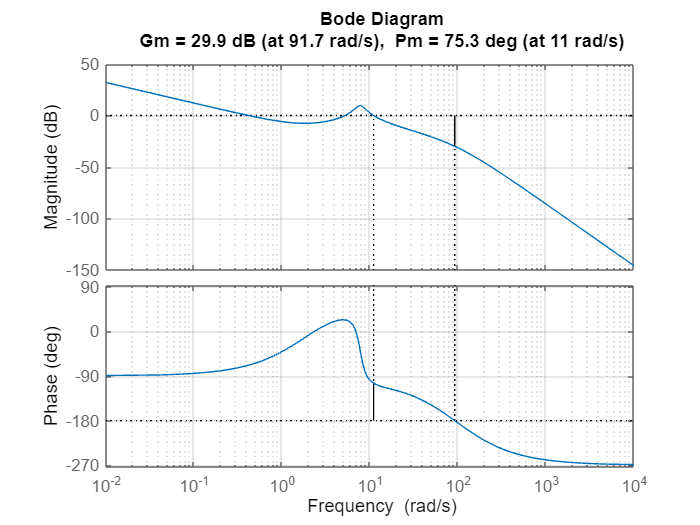

L_1=R_1*G;
margin(L_1)
grid

Tuttavia, studiando la risposta di F(s), si può verificare che il tempo di assestamento è decisamente più grande di quello richiesto dalla specifica.

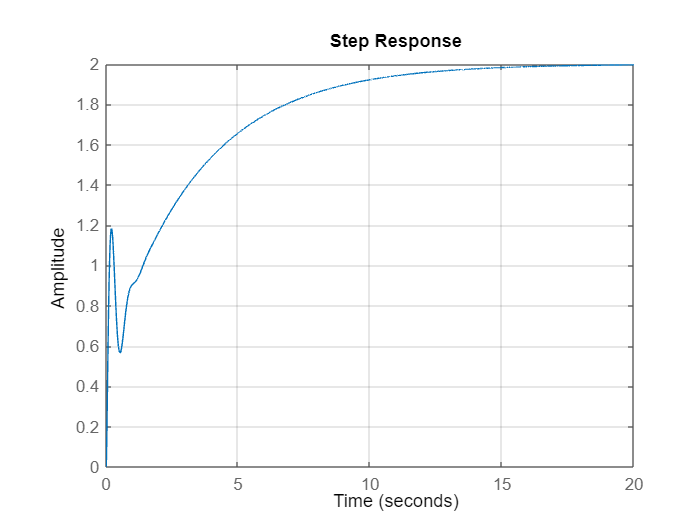

F_1=L_1/(1+L_1);
step(F_1,opt)
grid

Il sistema si assesta all'1% dopo 13.9 secondi, invece degli 0.8 richiesti dalle specifiche.

Questo errore è dato dalla presenza di una marcatissima coda di assestamento dal basso che ritarda la risposta del sistema. Studiando la posizione dei poli e degli zeri della F(s) si deduce che la coda è causata dalla quasi-cancellazione tra il polo nell'origine del regolatore statico e gli zeri del regolatore PID.

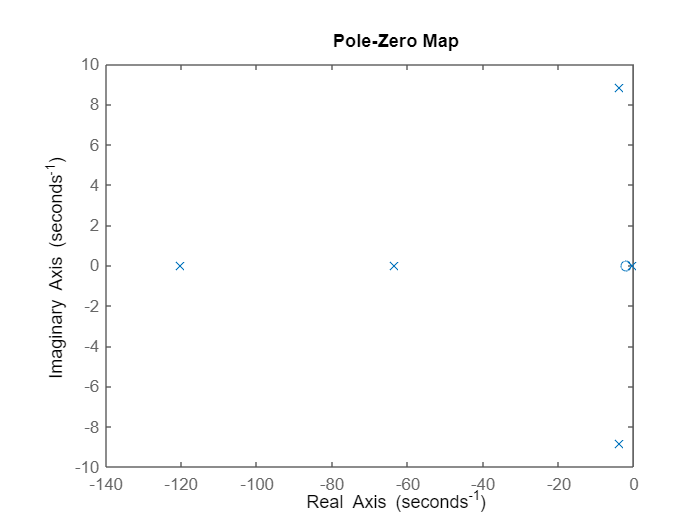

pzmap(minreal(F_1))

#### RIASSUNTO:

Si è imposto l'attraversamento a 11r/s per uscire dalla zona critica data dalla coppia di poli complessi coniugati.

Si è mantenuto il margine di fase pari a 75° come dedotto dalle specifiche dinamiche.

Si è usato un regolatore PID.

La risposta a gradino presenta una marcatissima coda di assestamento che porta il tempo di assestamento a 13.9 secondi.

### SCENARIO 2:

Per risolvere il problema della coda di assestamento in questo caso non è possibile agire per cancellazione, in quanto risulta molto rischioso cancellare il polo nell'origine del regolatore statico e l'unico polo reale del plant è ad una pulsazione più alta dell'intervallo di attraversamento voluto (gli zeri del regolatore dinamico devono necessariamente intervenire a pulsazione più bassa rispetto a quella di attraversamento). Di conseguenza, occorre trovare il modo di allontanare il più possibile gli zeri dal polo nell'origine.

Una possibile soluzione è quella di richiedere un minore margine di fase, ovvero una minore anticipazione da parte degli zeri, il che permetterebbe un loro intervento a pulsazioni più alte.

Potendo introdurre a posteriori un prefiltro per abbattere la sovraelongazione percentuale, si può considerare come margine di fase quello fornito dalle specifiche, ovvero Mf=40°, invece che quello dedotto in precedenza (Mf=75°).

Di conseguenza, si può calcolare la pulsazione di attraversamento  omegac_2 richiesta partendo da questa specifica più "permissiva" che permette, inoltre, di ridurre lo sforzo di controllo del regolatore.

delta_2=40/100;
omegac_2=4.6/(delta_2*0.8)

omegac_2 = 14.3750

Si possono ora ripetere i ragionamenti visti in precedenza considerando una nuova pulsazione di attraversamento omegac_2=14.4r/s e un nuovo margine di fase Mf=40°.

Posizionamento polo di fisica realizzabilità.

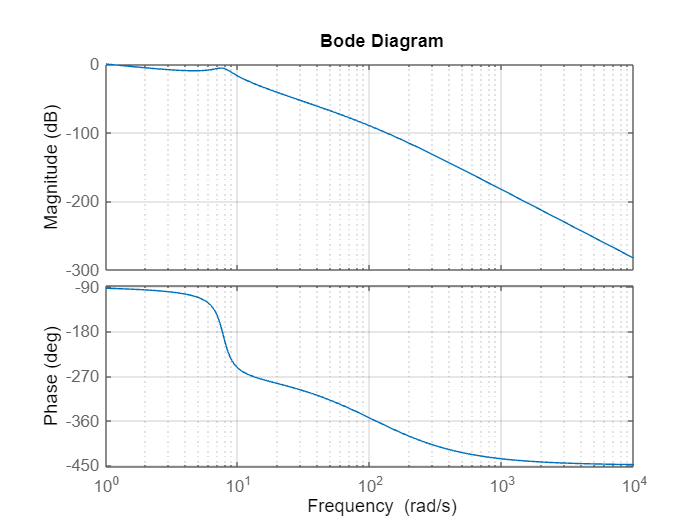

taup_2=1/(10*omegac_2);
Rd_2=1/(1+taup_2*s);
bode(Ge*Rd_2)
grid

In corrispondenza di 14.4r/s l'ampiezza risulta uguale a -30.9dB e la fase pari a -275°. È quindi necessaria un'amplificazione di 30.9dB e un'anticipazione di 135°.

Individuazione del valore di rho.

rho_2=tand(135/2);

Da cui si ricava il valore di tauz.

tauz_2=rho_2/omegac_2;

Si può ora definire il regolatore dinamico Rd_2.

Rd_2=(1+tauz_2*s)^2/(1+taup_2*s);

Scelta del guadagno statico mu:

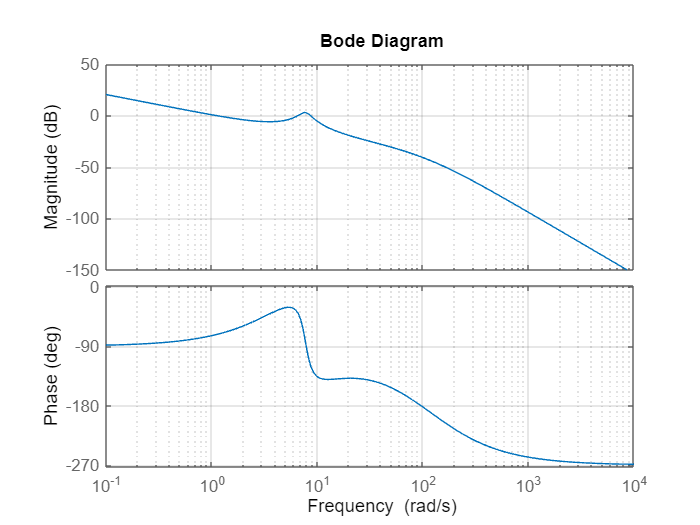

bode(Rd_2*Ge)
grid

Dallo studio del diagramma si deduce un'amplificazione necessaria di 14.2dB.

mu_2=10^(14.2/20)

mu_2 = 5.1286

Si può ora definire il regolatore R_2 finale:

R_2=mu_2*Rs*Rd_2

R_2 =
 
                            
  0.1447 s^2 + 1.723 s      
                            
                     + 5.129
                            
  --------------------------
                       
       0.006957 s^2 + s
                       
 
Continuous-time transfer function.



Si traccia il margin di L(s) per verificare che le specifiche siano state implementate correttamente.

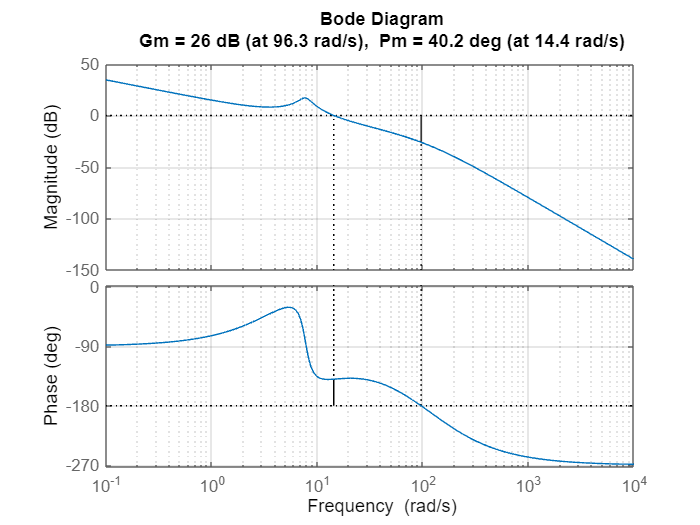

L_2=R_2*G;
margin(L_2)
grid

Tuttavia, studiando la risposta di F(s), si può verificare che ancora una volta il tempo di assestamento, seppur migliorato rispetto al caso precedente, rimane più grande di quello richiesto della specifica a causa di una coda di assestamento.

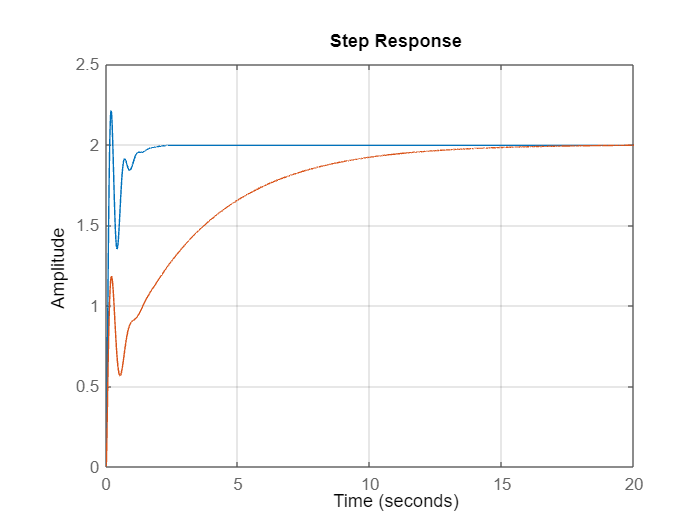

F_2=L_2/(1+L_2);
step(F_2,opt)
grid
hold on
step(F_1,opt)
hold off

Il sistema si assesta all'1% dopo 1.62 secondi, invece degli 0.8 richiesti dalle specifiche.

#### RIASSUNTO:

Si è deciso di adottare il margine di fase imposto da specifica per poter aumentare la pulsazione di attraversamento (14.4r/s) in modo da ridurre l'effetto della coda di assestamento.

Il tempo di assestamento si riduce significativamente (1.62 secondi), ma non a sufficienza.

### SCENARIO 3:

Un'altra possibilità per ridurre l'effetto della coda di assestamento è l'implementazione di un regolatore feedforward. Andando infatti subito in compensazione del segnale del riferimento, il regolatore permette di "bypassare" l'effetto della coda.

Pulsazione di attraversamento.

omegac_3=omegac_2

omegac_3 = 14.3750

Polo di fisica realizzabilità.

taup_3=1/(10*omegac_3);
Rd_3=1/(1+taup_3*s);
bode(Rd_3*Ge)
grid

Sfasamento necessario di 142° (viene scelto uno sfasamento maggiore per ottenere un margine di fase più "largo" che posso far fronte all'aggiunta di eventuali poli futuri).

Individuazione del valore di rho e tauz.

rho_3=tand(142/2);
tauz_3=rho_3/omegac_3;

Agli zeri è richiesto uno sfasamento di 71° gradi ciascuno che è un valore alto, ma rientra nelle specifiche del massimo sfasamento fisico degli zeri (circa 75°).

Definizione del regolatore dinamico.

Rd_3=(1+tauz_3*s)^2/(1+taup_3*s);

Scelta di mu.

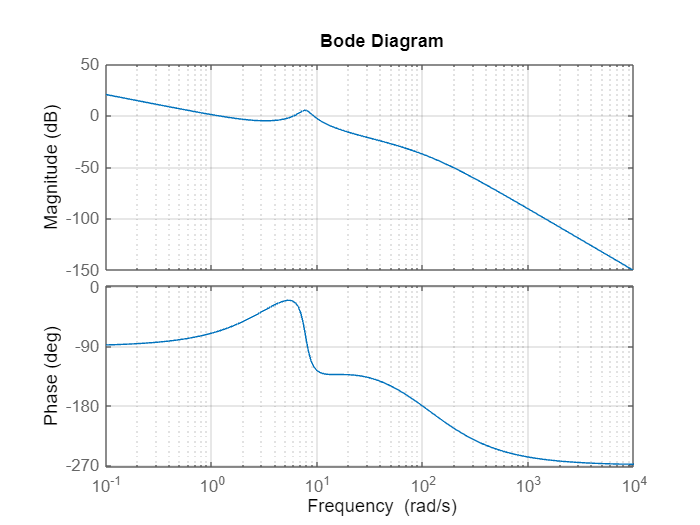

bode(Rd_3*Ge)
grid

mu_3=10^(11.4/20)

mu_3 = 3.7154

Definizione del regolatore.

R_3=mu_3*Rs*Rd_3

R_3 =
 
                            
  0.1516 s^2 + 1.501 s      
                            
                     + 3.715
                            
  --------------------------
                       
       0.006957 s^2 + s
                       
 
Continuous-time transfer function.



Verifica delle specifiche.

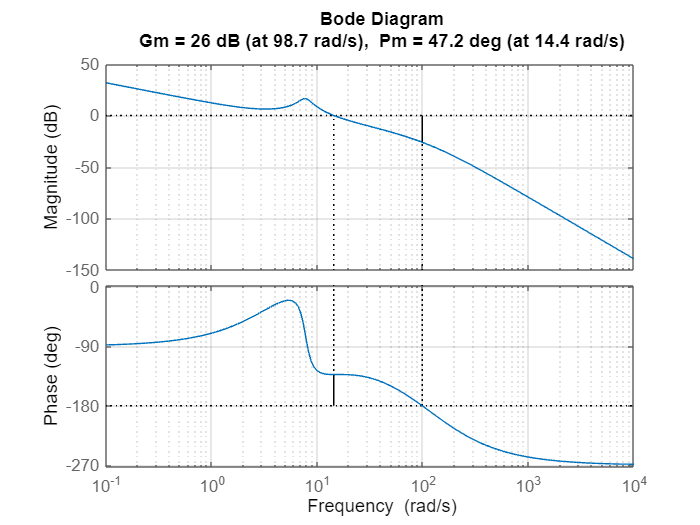

L_3=R_3*G;
margin(L_3)
grid

Il sistema attraversa a 14.4r/s con 47.2° di margine di fase (margine di fase volutamente più alto per far fronte all'eventuale inserimento di poli futuri).

Studio della risposta a gradino.

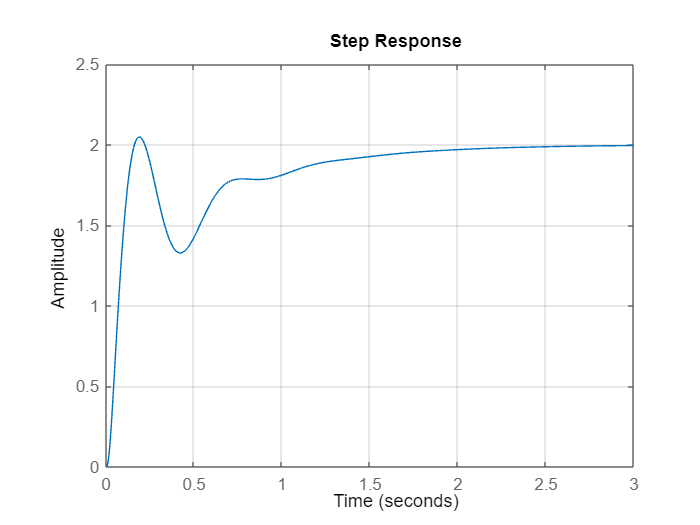

F_3=L_3/(1+L_3);
step(F_3,opt)
grid

Come visto nello Scenario 2 è presente una marcata coda di assestamento dal basso che porta il tempo di assestamento a 2.25 secondi.

Come già detto, un modo per ridurre l'effetto della coda di assestamento è l'introduzione di un **regolatore feedforward** che di conseguenza velocizza pesantemente il sistema.

L'obbiettivo è invertire G in bassa frequenza, tuttavia G in bassa frequenza non ha dinamiche (ad eccezione dei poli cc fortemente incerti).

Di conseguenza si decide di progettare Rff come inverso del guadagno statico di G, in modo da portare il prima possibile il sistema a regime.

mu_G=dcgain(G)

mu_G = 1.0417

Rff_3=1/mu_G

Rff_3 = 0.9600

Ora si vede che il tempo di assestamento del sistema è migliorato, ma non rientra ancora in specifica (0.856 secondi). Inoltre, la risposta presenta sovraelongazioni decisamente troppo elevate (51.6%).

Si decide dunque di implementare un **prefiltro frenante** del primo ordine per provare a far fronte a questi due problemi.

Rpf_3=1/(1+s/4.9)

Rpf_3 =
 
    4.9
  -------
  s + 4.9
 
Continuous-time transfer function.



Riducendo le oscillazioni si può verificare che è migliorato notevolmente anche il tempo di assestamento (il prefiltro frenante peggiora infatti il tempo di salita, ma non necessariamente quello di assestamento).

Studiando la risposta da Simulink si può verificare che ora il sistema rientra in specifica (0.87% di sovraelongazione e tempo di assestamento pari a 0.739 secondi).

open_system('Tesina_Scenario3.slx')

Per quanto riguarda la **funzione di sensibilità del controllo Q(s)**, si decide di aggiungere due poli di fisica realizzabilità per alzare il grado relativo del regolatore (e quindi abbattere Q(s)).

R_3=mu_3*Rs*Rd_3*(1/(1+(s/250))^2)

R_3 =
 
                            
  9478 s^2 + 9.383e04 s     
                            
                  + 2.322e05
                            
  --------------------------
                            
  0.006957 s^4 + 4.478 s^3  
                            
          + 934.8 s^2       
                            
                   + 62500 s
                            
 
Continuous-time transfer function.



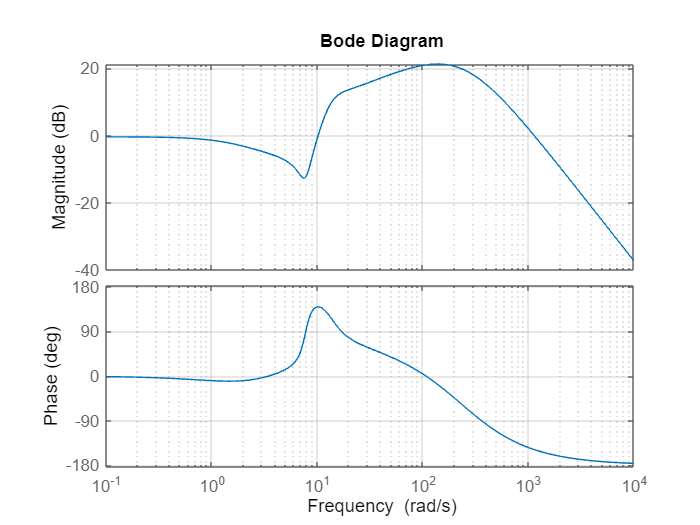

L_3=R_3*G;
Q_3=R_3/(1+L_3);
bode(Q_3)
grid

L'ampiezza di Q(s) ad alte frequenze (2000r/s) è ora pari a (-9.51dB). I disturbi di misura vengono quindi attenuati.

Si verifica che le specifiche siano ancora rispettate dopo l'introduzione dei due poli di fisica realizzabilità.

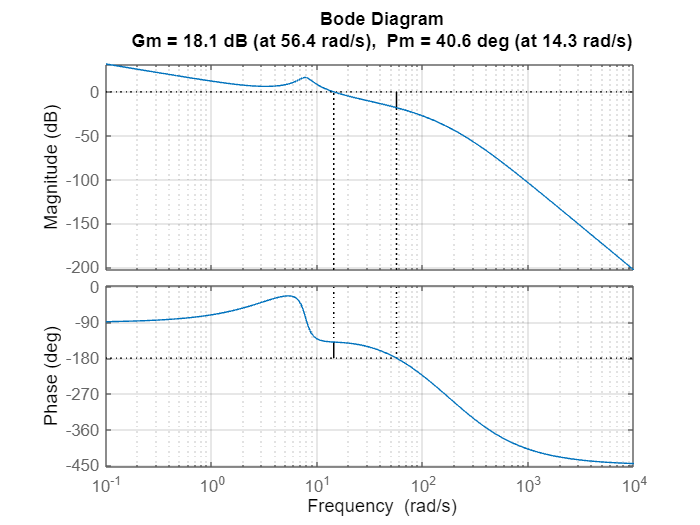

margin(L_3)
grid

Per quanto riguarda il **dimensionamento dell'attuatore**, studiando da Simulink l'andamento di u(t) si può notare che, grazie all'utilizzo di Rff, in condizioni nominali lo sforzo di controllo è decisamente basso, con un picco massimo di 1.93. Per questo motivo si può dimensionare l'attuatore con un livello di saturazione per il transitorio molto vicino a quello necessario per l'andamento a regime. A regime la u(t) ha un valore di 1.82, dato dalla somma dello sforzo del ramo di feedforward (1.92=2/mu_G) e dallo sforzo del ramo di retroazione (-0.1/mu_G) che serve a bilanciare l'effetto del disturbo d.

u_regime=2/mu_G-0.1/mu_G

u_regime = 1.8240

Il livello di saturazione si può portare fino a 1.9 senza avere praticamente alcuna modifica sull'andamento del sistema.

Il sistema nominale rispetta quindi perfettamente tutte le specifiche.

Tuttavia, il valore di G(s) è conosciuto solo nominalmente, bisogna di conseguenza aspettarsi delle **incertezze parametriche** che potrebbero far uscire il sistema dalle specifiche.

Ci si possono aspettare delle variazioni dell'ordine del 10% su omegan_G e su delta_G.

Si possono ora definire due nuove funzioni Ga(s) e Gb(s).

La prima si trova aumentando il valore dei due parametri.

omegan_Ga=omegan_G*1.1;
delta_Ga=delta_G*1.1;
Ga=((5000/(omegan_G^2))*(omegan_Ga^2))/((s+80)*(s^2+2*delta_Ga*omegan_Ga*s+omegan_Ga^2))

Ga =
 
                 
             6050
                 
  --------------------------
                            
  s^3 + 82.42 s^2           
                            
            + 266.2 s + 5808
                            
 
Continuous-time transfer function.



La seconda si trova diminuendone il valore.

omegan_Gb=omegan_G*0.9;
delta_Gb=delta_G*0.9;
Gb=((5000/(omegan_G^2))*(omegan_Gb^2))/((s+80)*(s^2+2*delta_Gb*omegan_Gb*s+omegan_Gb^2))

Gb =
 
                 
             4050
                 
  --------------------------
                            
  s^3 + 81.62 s^2           
                            
            + 178.2 s + 3888
                            
 
Continuous-time transfer function.



Si prova ora a simulare il sistema con i due nuovi plant Ga(s) e Gb(s).

Si può verificare che la risposta del plant Ga(s) risulta addirittura migliore di quella di G(s), ma la risposta di Gb(s) non rientra in specifica né in termini di sovraelongazione, né in termini di tempo di assestamento.

Il sistema non è quindi robusto a variazioni del 10% di delta e omegan.

In questo caso, il guadagno statico del plant non è cambiato. Si potrebbe quindi testare il sistema con variazioni del 10% direttamente sul guadagno statico.

Gc=G*1.1

Gc =
 
                 
             5500
                 
  --------------------------
                            
  s^3 + 82 s^2 + 220 s      
                            
                      + 4800
                            
 
Continuous-time transfer function.



Gd=G*0.9

Gd =
 
                 
             4500
                 
  --------------------------
                            
  s^3 + 82 s^2 + 220 s      
                            
                      + 4800
                            
 
Continuous-time transfer function.



Da Simulink si può verificare un'anomalia: oltre alla differenza in termini di sovraelongazione e tempo di assestamento delle risposte (prevista), solamente una delle risposte non si porta a regime correttamente. È il caso del sistema Gd(s) trovato con un aumento del 10%.

Diminuire del 10% il guadagno statico del plant porta ad una modifica del valore di regime dello sforzo di controllo u(t).

mu_Gd=dcgain(Gd)

mu_Gd = 0.9375

ud_regime=2/mu_Gd-0.1/mu_Gd

ud_regime = 2.0267

Risulta infatti un valore di u(t) a regime pari a 2.03, superiore quindi al limite di saturazione dell'attuatore definito in precedenza. Per questo motivo viene modificato il valore di regime del sistema.

Una soluzione può essere quella di ridimensionare l'attuatore con un livello di saturazione superiore a 2.03.

Dalla simulazione si può verificare che, dopo aver ridimensionato l'attuatore (saturazione a 2.1), tutti e tre i sistemi si assestano al valore corretto.

Tuttavia, il sistema Gd(s) presenta un tempo di assestamento di 0.818 secondi, mentre il sistema Gc(s) rientra in specifica.

Il sistema non rientra quindi nelle specifiche neanche a fronte di variazioni del 10% sul guadagno statico a causa dell'impiego di un regolatore feed-forward, molto poco robusto rispetto a variazioni di mu.

#### RIASSUNTO:

Si è deciso di implementare un regolatore feedforward pari all'inverso del guadagno statico di G(s) per fronteggiare l'effetto della coda di assestamento.

Questo porta ad un sistema più veloce, ma fortemente oscillante. Si è quindi utilizzato un prefiltro frenante per far rientrare il sistema in specifica.

Si sono successivamente aggiunti due poli di fisica realizzabilità nel regolatore abbattere l'ampiezza di Q(s) ad alte frequenze.

Si è infine trovato un livello di saturazione per l'attuatore ottimale per la G(s) nominale, ma che diventava problematico a fronte di incertezze. Il sistema non rientrava in specifiche né a fronte di variazioni del 10% su delta e omegan, né su mu. In quest'ultimo caso, inoltre, è stato necessario alzare il livello di saturazione affinché il sistema andasse quantomeno a regime correttamente.

### SCENARIO 4:

La soluzione appena proposta risulta quindi poco robusta ad incertezze del plant a causa della sua dipendenza del regolatore in feedforward. Si può quindi cercare un modo alternativo per ridurre le code di assestamento.

Una possibile soluzione è l'impiego di 3 zeri invece che 2. Questa soluzione permette di spostare l'intervento degli zeri a pulsazione più alta, allontanandoli dal polo nell'origine con cui vanno in quasi cancellazione.

Una prima possibilità è quella di prendere come riferimento lo Scenario  2, aggiungendo un ulteriore zero in corrispondenza dei due già presenti oltre ad un ulteriore polo di fisica realizzabilità per mantenere il grado relativo del regolatore non negativo.

La pulsazione di attraversamento omegac_4 coincide con quella del secondo scenario.

omegac_4=omegac_2

omegac_4 = 14.3750

Si può ora già definire la posizione dei due poli di fisica  realizzabilità.

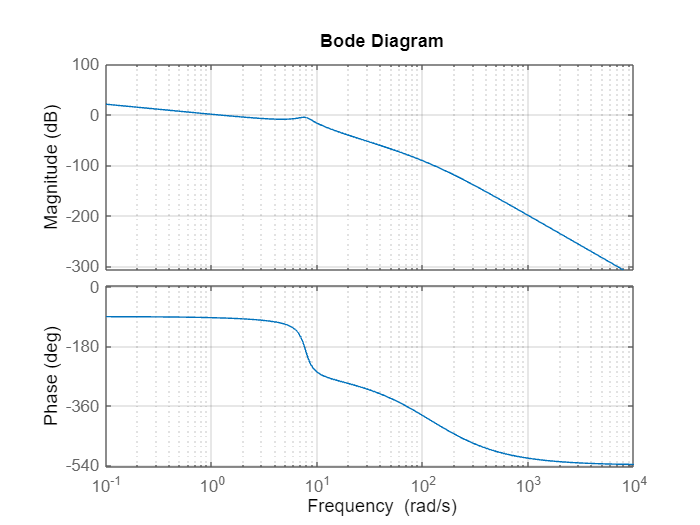

taup_4=1/(10*omegac_4);
Rd_4=1/(1+taup_4*s)^2;
bode(Ge*Rd_4)
grid

È necessaria un'amplificazione di 30.9dB e un'anticipazione di 140°.

Individuazione del valore di rho e tauz.

rho_4=tand(140/3);
tauz_4=rho_4/omegac_4;

Si può ora definire il regolatore dinamico Rd_4.

Rd_4=(1+tauz_4*s)^3/(1+taup_4*s)^2;

Scelta del guadagno statico mu.

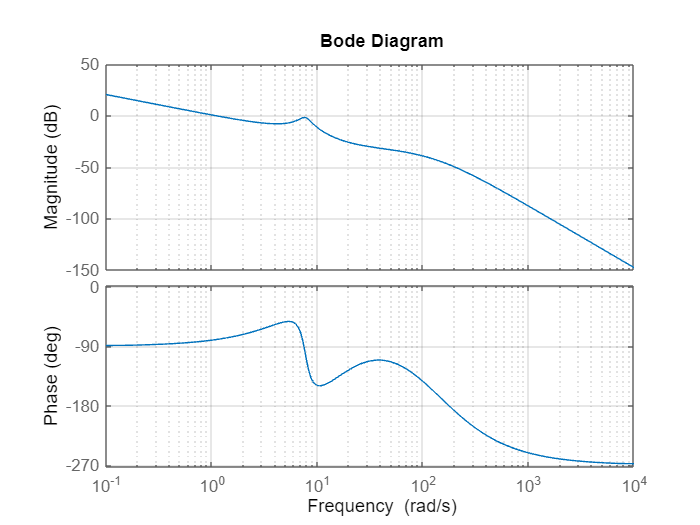

bode(Rd_4*Ge)
grid

mu_4=10^(21.4/20)

mu_4 = 11.7490

Si può ora definire il regolatore R finale.

R_4=mu_4*Rs*Rd_4

R_4 =
 
                             
   0.00471 s^3 + 0.1916 s^2  
                             
            + 2.599 s + 11.75
                             
  ----------------------------
                              
  4.839e-05 s^3 + 0.01391 s^2 
                              
                         + s  
                              
 
Continuous-time transfer function.



Si traccia il margin di L(s) per verificare che le specifiche siano state implementate correttamente.

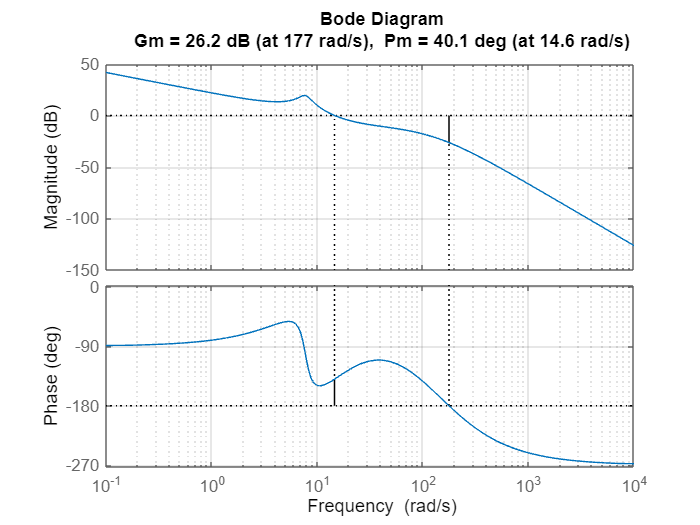

L_4=R_4*G;
margin(L_4)
grid

Studiando la risposta di F(s) si può notare un andamento caratterizzato da discrete sovraelongazioni e oscillazioni.

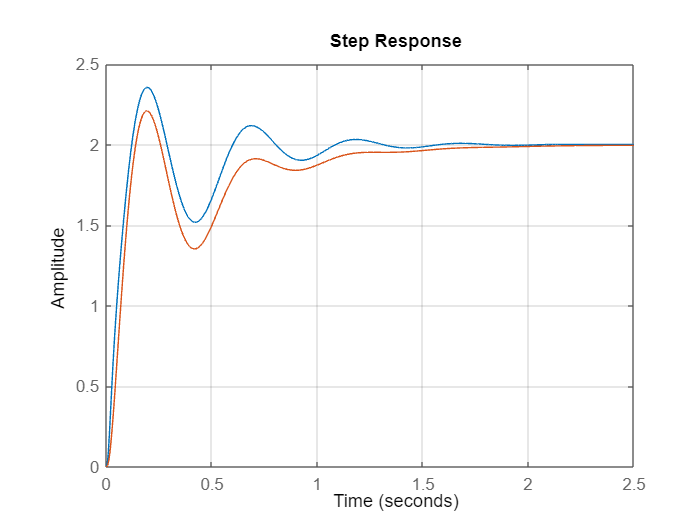

F_4=L_4/(1+L_4);
step(F_4,opt)
grid
hold on
step(F_2,opt)
hold off

Tuttavia, l'effetto della coda di assestamento sembra essere inesistente.

È interessante verificare che, grazie all'utilizzo di 3 zeri nel regolatore, il polo nell'origine di L(s) tende a spostarsi a pulsazioni più alte rispetto alla coppia dei poli complessi coniugati quando vi è la chiusura in retroazione. Ciò rende la coppia dei poli complessi coniugati la dinamica dominante di F(s), annullando l'effetto della coda di assestamento.

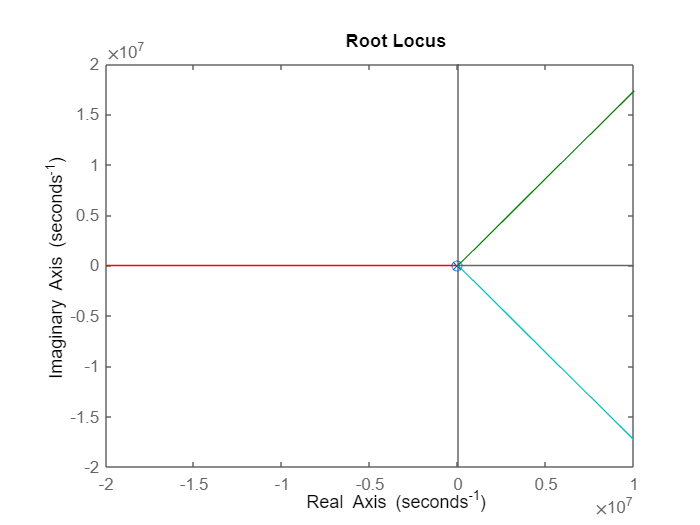

rlocus(L_4)

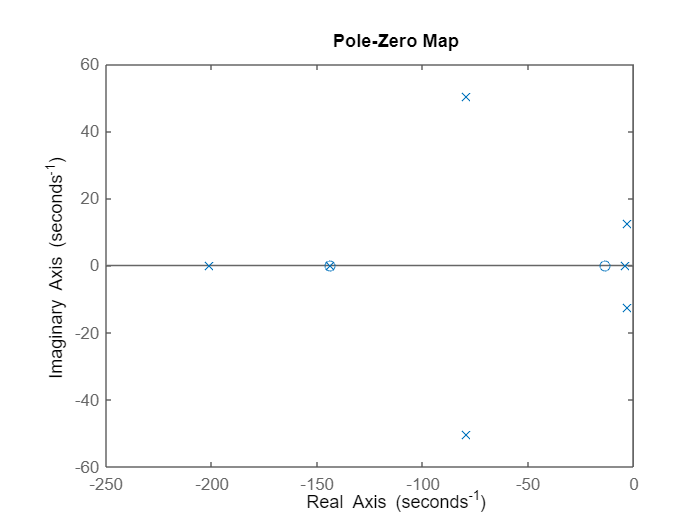

pzmap(minreal(F_4))

Per verificare se effettivamente il tempo di assestamento del sistema rispetta le specifiche, si decide di progettare un prefiltro frenante del secondo ordine reale per attenuare le sovraelongazioni della risposta e consentire una lettura più efficace del grafico (l'attenuazione delle sovraelongazioni è richiesta in ogni caso da specifiche).

Si usa un ciclo for per determinare la pulsazione di rottura w che riduce le sovraelongazioni al 5%.

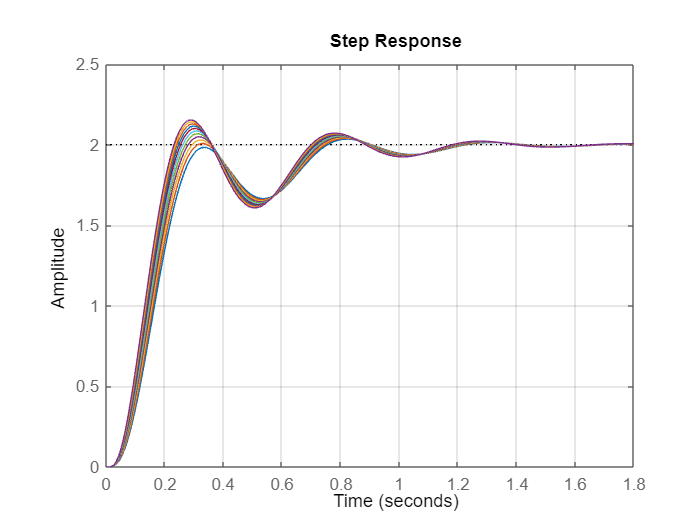

for w=10:0.5:15
Rpf=1/(1+s*(0.65/w))^2;
step(Rpf*feedback(L_4,1),opt)
grid
hold on
end
hold off

Dal grafico si deduce che il valore w ideale è 13.

Rpf_4=1/(1+s*(0.65/13))^2

Rpf_4 =
 
            1
  ----------------------
  0.0025 s^2 + 0.1 s + 1
 
Continuous-time transfer function.



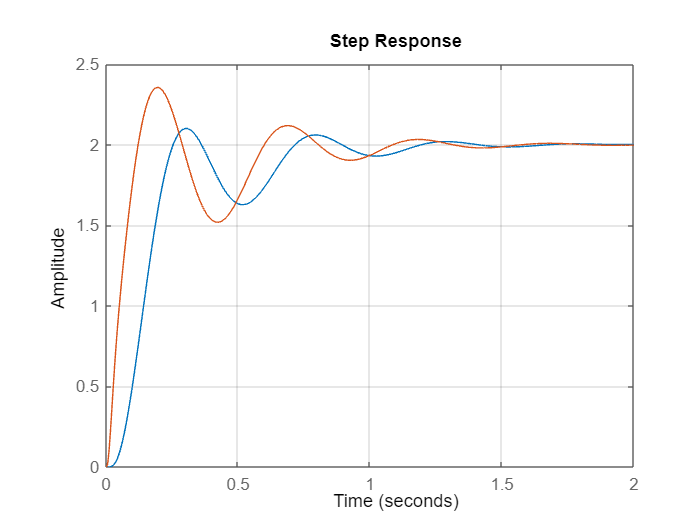

step(Rpf_4*F_4,opt)
grid
hold on
step(F_4,opt)
hold off

Riducendo le sovraqelongazioni sotto una soglia accettabile si può verificare che neanche questa volta il sistema si assesta abbastanza velocemente (Ta=1.14 secondi).

#### RIASSUNTO:

Si è deciso di adottare 3 zeri nel regolatore per poter da un lato avvicinare l'intervento degli zeri alla pulsazione di attraversamento (e quindi allontanarlo dall'origine) dall'altro poter aumentare ulteriormente la pulsazione di attraversamento senza doversi preoccupare del massimo sfasamento degli zeri.

Si sono inseriti un ulteriore zero e un ulteriore polo di fisica realizzabilità all'interno del PID.

Si ottiene un sistema privo di coda di assestamento, ma con marcate oscillazioni. Dopo l'utilizzo di un prefiltro frenante per moderare le oscillazioni al di sotto della specifica, si ottiene ancora una volta un sistema troppo lento (Ta=1.14 secondi).

### SCENARIO 5:

Essendo il sistema ancora troppo lento, si decide di imporre una pulsazione di attraversamento più alta.

Grazie all'impiego di tre zeri nel regolatore, infatti, non si hanno più limiti stringenti legati alla massima anticipazione attuabile da uno zero dal punto di vista fisico (circa 75°).

Si individua la pulsazione di 23r/s.

omegac_5=23

omegac_5 = 23

Si può ora definire la posizione dei due poli di fisica realizzabilità.

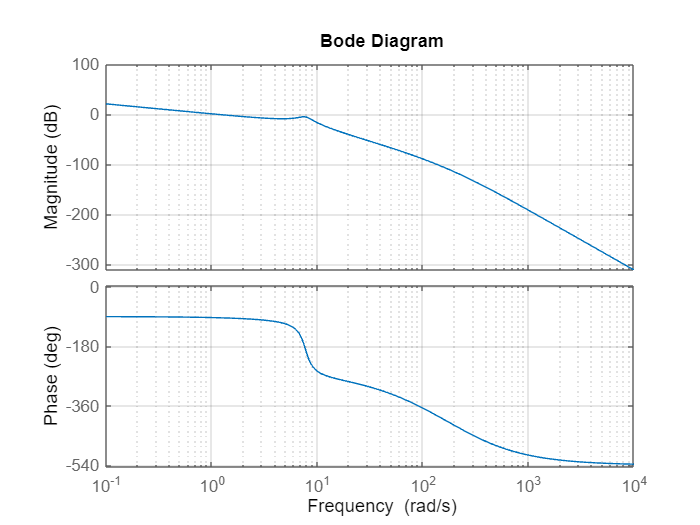

taup_5=1/(10*omegac_5);
Rd_5=1/(1+taup_5*s)^2;
bode(Ge*Rd_5)
grid

È necessaria un'amplificazione di 45.2dB e un'anticipazione di 152°.

Individuazione del valore di rho e tauz.

rho_5=tand(152/3);
tauz_5=rho_5/omegac_5;

Si può ora definire il regolatore dinamico Rd_5.

Rd_5=(1+tauz_5*s)^3/(1+taup_5*s)^2;

Scelta del guadagno statico mu.

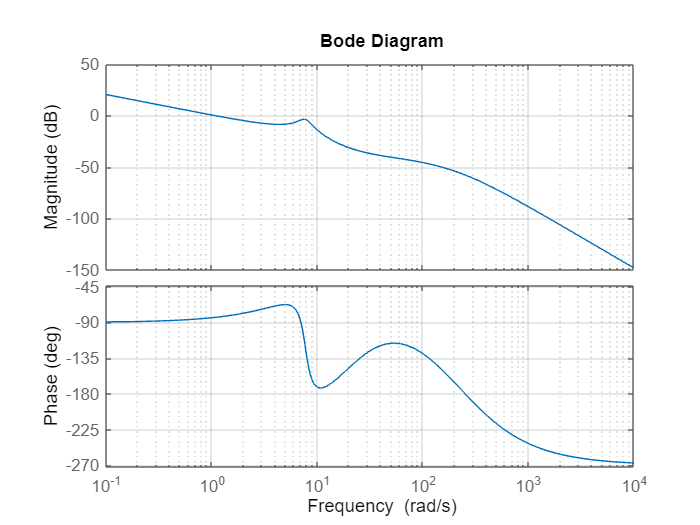

bode(Rd_5*Ge)
grid

mu_5=10^(33.3/20)

mu_5 = 46.2381

Si può ora definire il regolatore R finale.

R_5=mu_5*Rs*Rd_5

R_5 =
 
                             
   0.006906 s^3 + 0.3905 s^2 
                             
             + 7.36 s + 46.24
                             
  ----------------------------
                              
  1.89e-05 s^3 + 0.008696 s^2 
                              
                         + s  
                              
 
Continuous-time transfer function.



Si traccia il margin di L(s) per verificare che le specifiche siano state implementate correttamente.

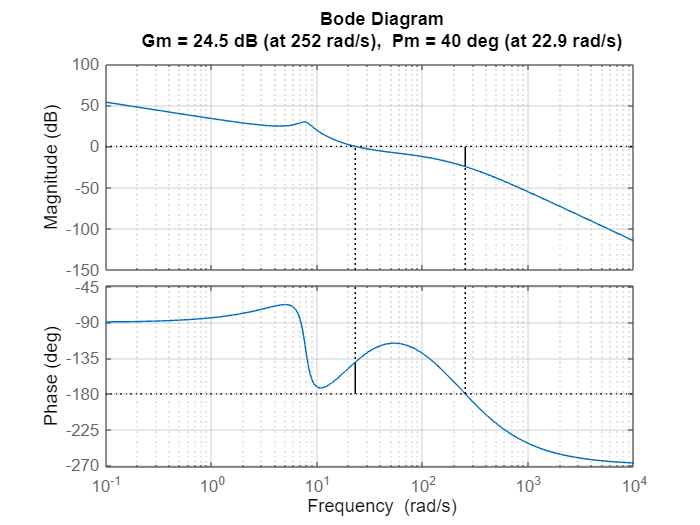

L_5=R_5*G;
margin(L_5)
grid

Si può studiare la risposta a gradino della funzione F_5.

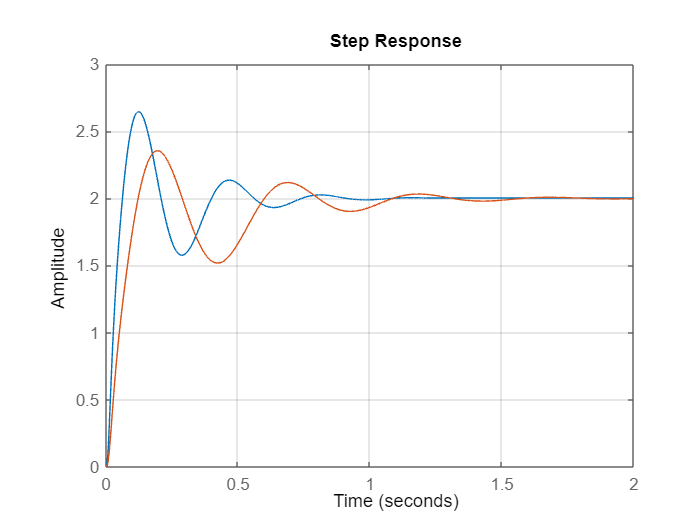

F_5=L_5/(1+L_5);
step(F_5,opt)
grid
hold on
step(F_4,opt)
hold off

Anche questa volta la risposta è caratterizzata da forti sovraelongazioni, ma sembra decisamente più veloce rispetto al caso precedente .

Ancora una volta si impiega un prefiltro frenante per studiare al meglio la risposta del sistema.

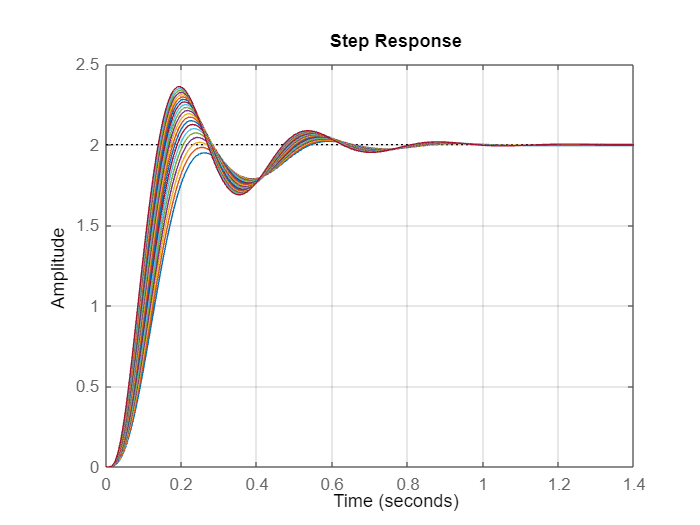

for w=10:0.5:20
Rpf=1/(1+s*(0.65/w))^2;
step(Rpf*feedback(L_5,1),opt);
grid
hold on
end
hold off

Dal grafico si deduce che il valore w ideale è 12.5.

Rpf_5=1/(1+s*(0.65/12.5))^2

Rpf_5 =
 
              1
  --------------------------
  0.002704 s^2 + 0.104 s + 1
 
Continuous-time transfer function.



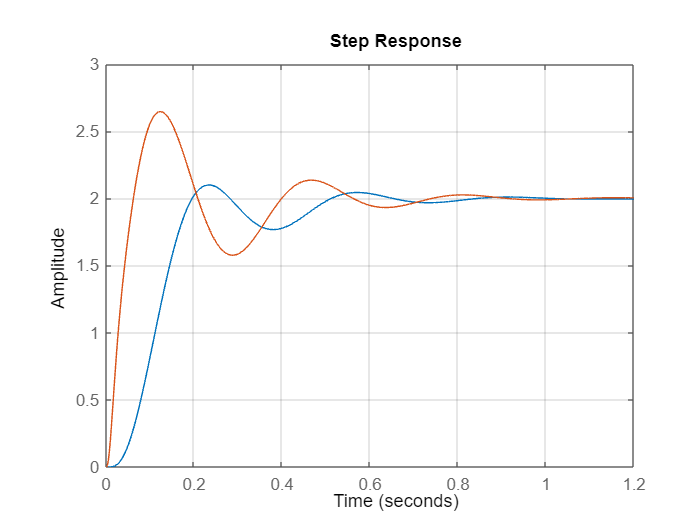

step(Rpf_5*F_5,opt)
grid
hold on
step(F_5,opt)
hold off

Questa volta, dopo aver applicato il prefiltro, la risposta rispetta in maniera piuttosto precisa le specifiche dinamiche imposte (Ta=0.777sec e S%=4%).

Tuttavia, aver imposto un attraversamento ad una pulsazione ben più alta di quella identificata in origine ha avuto effetti molto negativi sulla funzione di sensibilità del controllo Q(s).

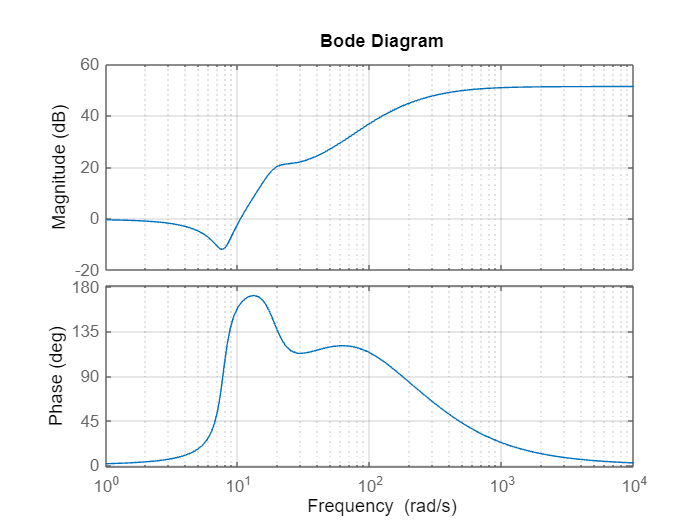

Q_5=R_5/(1+L_5);
bode(Q_5)
grid

Si prova ad abbattere il valore di Q(s) ad alte frequenze posizionando due poli a pulsazione elevata (200r/s).

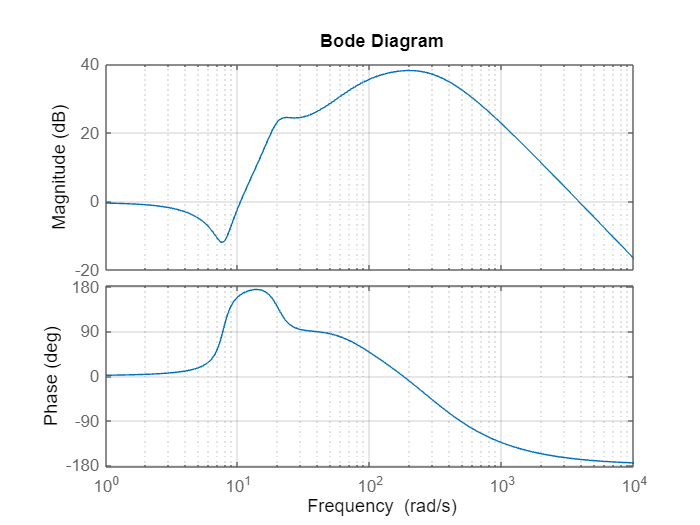

R_5p=R_5*(1/(1+s/200)^2);
L_5p=R_5p*G;
Q_5p=R_5p/(1+L_5p);
bode(Q_5p)
grid

Anche posizionando due poli ad alta frequenza il sistema non riesce ad attenuare a sufficienza eventuali disturbi di misura presenti ad alte frequenze (a 2000r/s Q(s) ha un valore di 11.1dB).

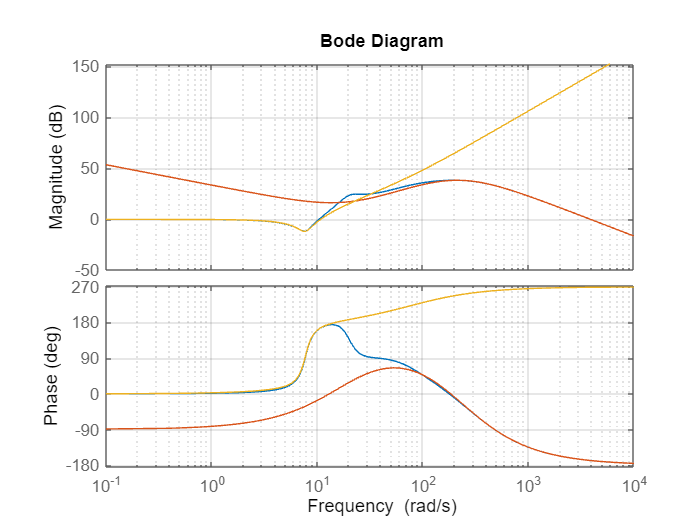

bode(Q_5p,R_5p,1/G)
grid

Sovrapponendo al bode di Q(s) i grafici di R(s) e 1/G(s) si può notare che l'alto valore di Q(s) in alta frequenza è dato da R(s) (e non tanto da una pulsazione di attraversamento troppo alta). Il motivo di un valore così alto di R(s) è che, nonostante il grado relativo sia -2, i tre zeri intervengono a pulsazioni molto più basse di 4 dei 5 poli (poli di fisica realizzabilità).

#### RIASSUNTO:

Si è trovata una pulsazione di attraversamento un po' più alta della precedente per velocizzare il sistema (23r/s).

Si ottiene un sistema che rispetta sia le specifiche di sovraelongazione (S%=4%) che di tempo di assestamento (0.777 secondi).

Tuttavia, il sistema presenta un ampiezza della funzione di sensibilità del controllo ad alte frequenze piuttosto grande (11.1dB) nonostante l'impiego di due poli di fisica realizzabilità.

### SCENARIO 6:

Una possibile soluzione potrebbe essere quella di abbandonare la struttura del PID (in realtà sarebbe un sorta di "PID potenziato") e provare ad agire con una tripla rete anticipatrice. In questo modo anche la pulsazione di intervento dei poli sarebbe più bassa e potrebbero abbattere prima l'ampiezza di R(s) e, conseguentemente, di Q(s).

Dovendo "contrastare" l'effetto di poli più vicini all'attraversamento rispetto al caso precedente, ci si aspetta che gli zeri debbano intervenire a pulsazioni più basse avvicinandosi pericolosamente al polo nell'origine ricreando l'effetto della coda di assestamento. Di conseguenza si sceglie una pulsazione di attraversamento più alta del caso precedente.

omegac_6=30

omegac_6 = 30

Impiegando 3 reti anticipatrici ci si aspetta di dover impiegare un solo polo di fisica realizzailità in modo da rendere uguale a 2 il grado relativo del regolatore. Come negli altri casi si sceglie di progettarlo subito in modo da poterne studiare al meglio l'effetto in termini di attenuazione e sfasamento.

taup_6=1/(10*omegac_6);
Rd_6=1/(1+taup_6*s);

Si cercano ora l'amplificazione e lo sfasamento richiesti alle 3 reti anticipatrici.

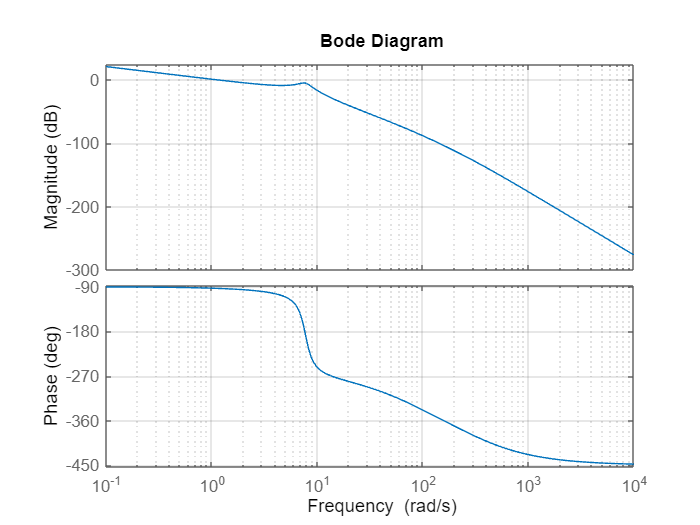

bode(Ge*Rd_6)
grid

Risulta un'amplificazione necessaria di 52.8dB e uno sfasamento di 154°.

Studiando il grafico del picco di sfasamento per uno sfasamento necessario di 154°/3=51.3° si trova il valore di alpha.

alpha_6=0.122;

Da cui si può ricavare il valore di tau.

tau_6=1/(omegac_6*sqrt(alpha_6));

Si può ora definire il regolatore dinamico completo.

Rd_6=(1+tau_6*s)^3/((1+alpha_6*tau_6*s)^3*(1+taup_6*s));

Si trova ora il valore di mu.

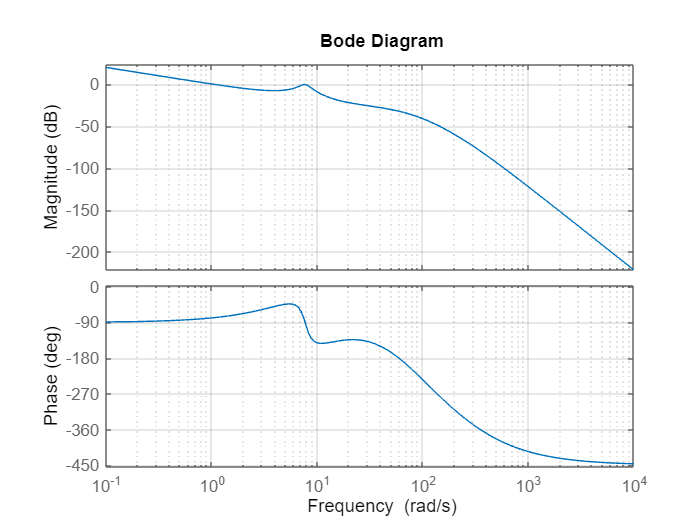

bode(Ge*Rd_6)
grid

mu_6=10^(25.3/20)

mu_6 = 18.4077

Si possono ora definire R(s) e L(s) per poter verificare che le specifiche siano rispettate.

R_6=mu_6*Rs*Rd_6

R_6 =
 
                              
    0.016 s^3 + 0.5029 s^2    
                              
              + 5.27 s + 18.41
                              
  ------------------------------
                                
  5.261e-09 s^5 + 2.934e-06 s^4 
                                
          + 0.0005231 s^3       
                                
           + 0.03826 s^2 + s    
                                
 
Continuous-time transfer function.



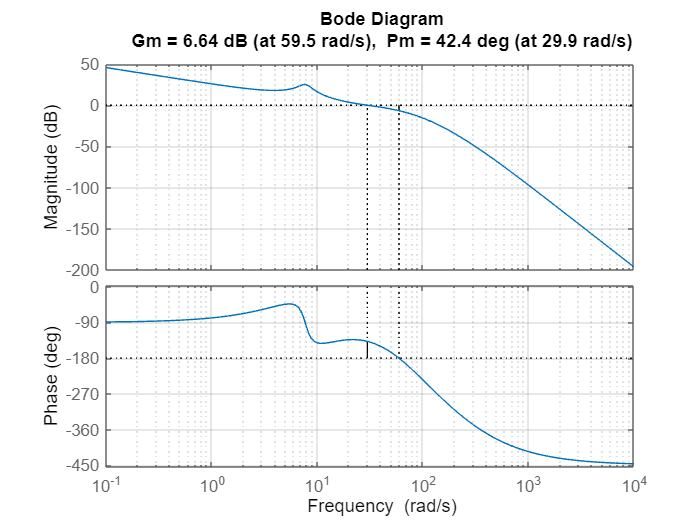

L_6=G*R_6;
margin(L_6)
grid

Il sistema attraversa a 29.9r/s con 42.4° di margine di fase (si è lasciato un margine di fase leggermente maggiore di quello a specifica per far fronte ad eventuali operazioni future).

Si studia ora la risposta a gradino della F(s).

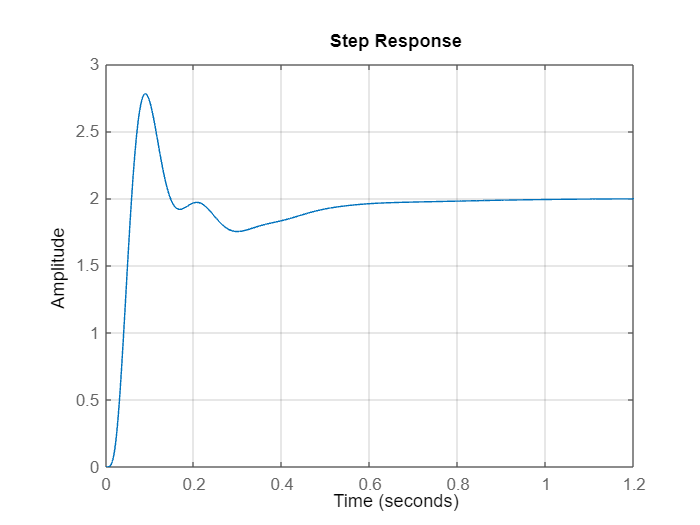

F_6=L_6/(1+L_6);
step(F_6,opt)
grid

In termini di tempo di assestamento il sistema rientra largamente in specifica. Tuttavia, presenta una sovraelongazione di valore eccessivo.

Si decide quindi di implementare un prefiltro frenante come in precedenza in modo da ridurre la sovraelongazione (il codice è commentato per evitare di allungare i tempi in esecuzioni successive).

% for w=15:0.5:25
% Rpf=1/(1+s/w);
% step(Rpf*feedback(L_6,1),opt);
% grid
% hold on
% end
% hold off

Il valore di w necessario è 19.5.

Rpf_6=1/(1+s*1/19.5)

Rpf_6 =
 
    19.5
  --------
  s + 19.5
 
Continuous-time transfer function.



Si può ora verificare se il sistema complessivo rispetta le specifiche.

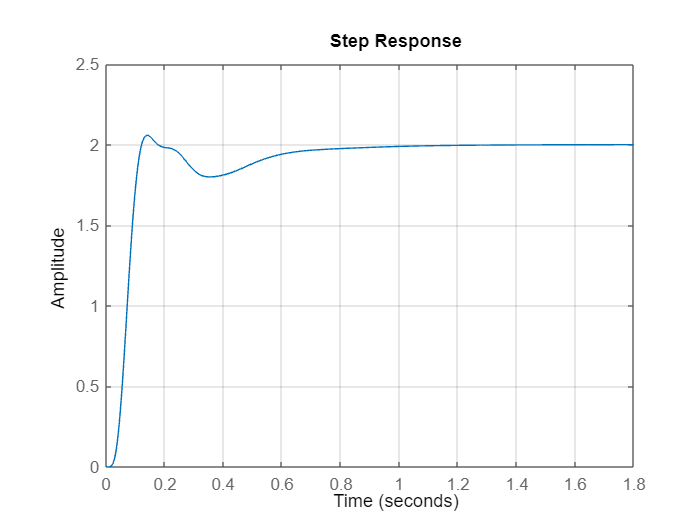

step(Rpf_6*F_6,opt)
grid

Il sistema si assesta all'1% dopo 0.797 secondi presentando una massima sovraelongazione del 3%.

Si può ora studiare la Q(s) del sistema per vedere se, ad alte frequenze, il sistema attenua o amplifica i disturbi.

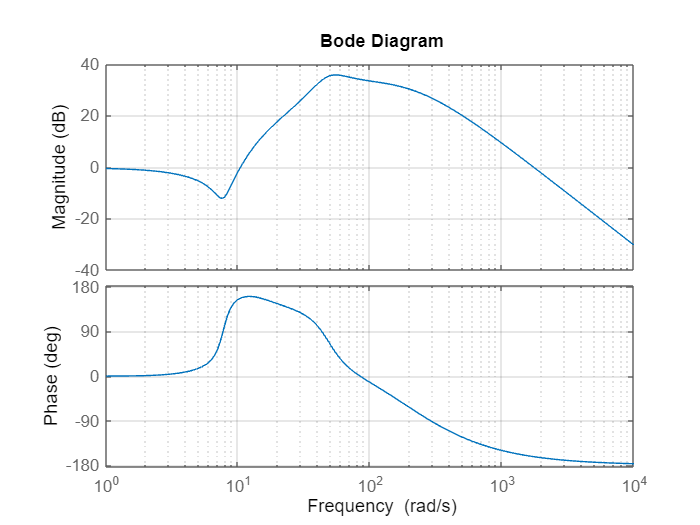

Q_6=R_6/(1+L_6);
bode(Q_6)
grid

Questa volta, a una pulsazione di 2000r/s la Q(s) ha un valore di -2.5dB. Il che significa che a quella pulsazione il sistema attenua gli eventuali disturbi, anche se l'attenuazione non è particolarmente grande.

Il valore di Q si potrebbe far crollare ulteriormente inserendo un secondo polo di fisica realizzabilità.

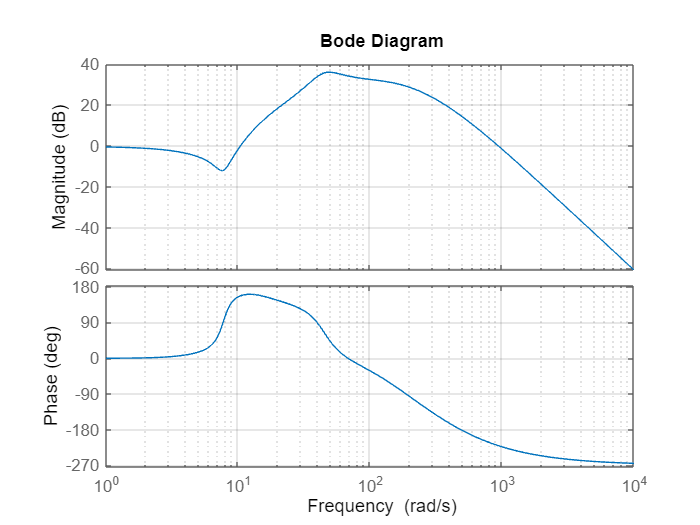

bode((R_6*(1/(1+taup_6*s)))/(1+L_6*(1/(1+taup_6*s))))
grid

In questo modo a 2000r/s l'ampiezza di Q(s) è pari a -19.1dB. Tuttavia, questo sistema inserisce un ulteriore polo che rende più complesso il sistema, oltre ad avere influenze (seppur ridotte) a livello di attraversamento e margine di fase.

Tuttavia, un modo di sfruttare al meglio un filtro del primo primo ordine necessario per l'operazione appena descritta è quello di impiegarlo come filtro anti-aliasing. In questo modo, oltre ad evere un effetto benefico in termini di sensibilità del controllo in questo caso necessario, avrà anche un effetto positivo per contrastare il fenomeno dell'aliasing, pemettendo una scelta meno "severa" del tempo di campionamento T. In questo modo si può "far fronte" alla maggiore complessità del sistema data dal polo aggiuntivo semplificando l'opera di discretizzazione grazie a specifiche su T meno stringenti (senza compromettere l'efficienza del sistema).

Haa_6=1/(1+s/800)

Haa_6 =
 
    800
  -------
  s + 800
 
Continuous-time transfer function.



La pulsazione di rottura (800r/s) è leggermente più alta rispetto a quella del polo di fisica realizzabilità (300r/s) in modo da diminuire ulteriormente gli effetti alla pulsazione di attraversamento.

Si può ora valutare l'effetto benefico su Q(s)

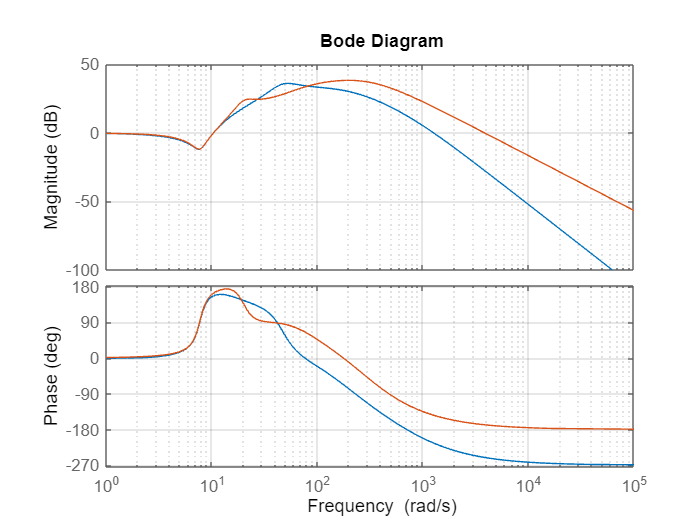

Qaa_6=(R_6*Haa_6)/(1+L_6*Haa_6);
bode(Qaa_6)
grid
hold on
bode(Q_5p)
hold off

Ora il l'ampiezza di Q(s) a 2000r/s è pari a -11.1dB, che equivale ad un'attenuazione più che sufficiente per far fronte ai disturbi di misura presenti.

Si può fare un controllo sullo step dell'intero sistema per verificare che le specifiche di sovraelongazione e tempo di assestamento vengano mantenute.

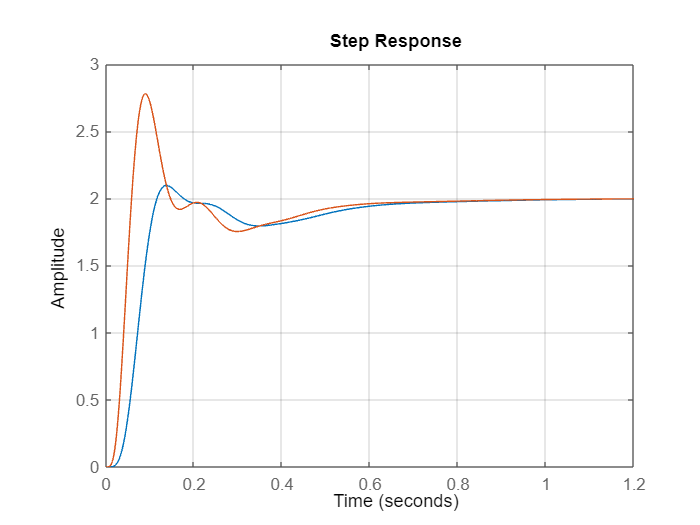

step(Rpf_6*(L_6/(1+L_6*Haa_6)),opt)
grid
hold on
step(F_6,opt)
hold off

Il sistema con il filtro anti aliasing ha sovraelongazioni leggermente maggiori di prima (5%) e tempo di assestameto praticamente uguale (0.796). Questi valori rientrano comunque tutti in specifica.

Mancano ora le considerazioni sull'attuatore.

Come già detto u(t) a regime ha un valore pari a due volte l'inverso del guadagno statico di G(s) meno lo 0.1 dovuto al disturbo di tipologia d (u_regime=1.82).

open_system('Tesina_Scenario6.slx')

Come si può infatti constatare anche dallo scope della variabile u(t) da Simulink, il valore a regime è pari a 1.82. Ciò è dovuto all'intervento del disturbo d di ampiezza 0.1 che porta la u totale ad essere 1.82. In questo modo, le due ampiezze sommate forniscono un valore totale pari a 1.92 (l'inverso di mu_G).

Questo significa che, al fine di garantire il funzionamento a regime, l'attuatore essere dimensionato minimo a 1.82.

Per quanto riguarda il transitorio, invece, studiando l'andamento di u(t) da Simulink, si può notare che il picco maggiore è pari a 15.7. Verrebbe quindi da dire che, avendo specifiche sul tempo di assestamento molto strette, l'attuatore deve essere simensionato come minimo intorno a 15.7.

Tuttavia, andando ad inserire livelli di saturazione minori di 15.7, si può verificare che non solo le specifiche non peggiorano, ma in parte migliorano. Ad esempio, con un livello di saturazione pari a 8, tramite simulazione si può verificare che la sovraelongazione scende al di sotto del 2% e il tempo di assestamento rimane intorno a 0.795 secondi.

Il principio per cui avviene questo comportamento è lo stesso relativo al Rpf usato in precedenza: il tempo di salita cresce come previsto, ma clippando il valore di u(t), vengono ridotti anche i picchi di y(t)=u(t)*G. Questa riduzione dell'ampiezza delle oscillazioni di y(t) riduce il tempo di assestamento effettivo.

Tramite questo ragionamento il livello di saturazione dell'attuatore può scendere fino ad un valore di 5.67. Per valori più bassi la sovraelongazione supera il limite del 5% richiesto da specifica.

Con un livello di saturazione di 5.67 il sistema si assesta all'1% dopo 0.647 secondi presentando una massima sovraelongazione pari al 4.99%.

Si può ora provare a testare il sistema a fronte di incertezze del 10% su delta e omegan. Si usano quindi le due funzioni Ga(s) e Gb(s) definite in precedenza.

Provando a simulare il sistema con il plant Ga si ottengono i seguenti valori:

Il sistema si assesta all'1% dopo 0.636 secondi presentando una massima sovraelongazione pari al 2.65%.

Provando a simulare il sistema con il plant Gb si ottengono i seguenti valori:

Il sistema si assesta all'1% dopo 0.654 secondi presentando una massima sovraelongazione pari al 10.4%.

Si può quindi verificare che aumentando del 10% il valore di omegan_G e delta_G il sistema rimane perfettamente in specifica. Diminuendo il valore, invece, il sistema presenta una sovraelongazione leggermente fuori specifica, ma un tempo di assestamento adeguato.

Per migliorare le prestazioni del sistema variazioni del 10% sia per eccesso che per difetto, si può modificare il livello di saturazione dell'attuatore.

Ad esempio, con un livello di saturazione di 8.0, Gb(s) ha una sovraelongazione pari al 7.65%, quindi leggermente migliori di prima.

Si può ripetere la valutazione con variazioni sul guadagno statico. CI si aspetta una robustezza maggiore rispetto allo scenario 3, quindi si decide di attuare variazioni fino al 20%.

Gf=1.2*G

Gf =
 
                 
             6000
                 
  --------------------------
                            
  s^3 + 82 s^2 + 220 s      
                            
                      + 4800
                            
 
Continuous-time transfer function.



Gg=0.8*G

Gg =
 
                 
             4000
                 
  --------------------------
                            
  s^3 + 82 s^2 + 220 s      
                            
                      + 4800
                            
 
Continuous-time transfer function.



Si simulano poi i due sistemi su Simulink.

Le prestazioni peggiorano leggermente diminuendo il valore di mu, ma il sistema si assesta comunque in 0.765 con una sovraelongazione del 3.85%.

Questo risultato rappresenta un vantaggio che questa rete ha rispetto a quella desrcritta nello scenario 3. Infatti, non impiegando un regolatore feed-forward, il sistema risulta in generale più robusto.

Per quanto riguarda la discretizzazione del sistema, non dovendo fare considerazioni "severe" sul costo dell'hardware, si può scegliere un valore intermedio per alpha.

alpha_6=6;

Possiamo inoltre considerare omegas più grande possibile.

omegas_6=10*alpha_6*omegac_6

omegas_6 = 1800

In questo modo vengono rispettate tutte le specifiche (omegas risulta essere 60 volte omegac e più del doppio della pulsazione di rottura del filtro anti-aliasing).

A questo punto si può definire il tempo di campionamento T.

T_6=2*pi/omegas_6

T_6 = 0.0035

Si può a questo punto definire il regolatore discreto Rd(z).

Rdis_6=c2d(R_6,T_6,'tustin')

Rdis_6 =
 
                            
  4.222 z^5 - 3.767 z^4     
                            
          - 8.428 z^3       
                            
          + 7.551 z^2       
                            
           + 4.206 z - 3.783
                            
  ---------------------------
                             
  z^5 - 3.53 z^4 + 4.864 z^3 
                             
          - 3.25 z^2         
                             
          + 1.043 z - 0.1263 
                             
 
Sample time: 0.0034907 seconds
Discrete-time transfer function.



Si è scelto il metodo Tustin in quanto risulta il più preciso non avendo problemi riguardo il tempo di elaborazione.

S infine la funzione tfdata per poter implementare su Simulink il regolatore appena progettato.

[NUMd,DENd,Tz_6]=tfdata(Rdis_6,'v');

Per discretizzare il prefiltro si usa la stessa procedura.

Rpfdis_6=c2d(Rpf_6,T_6,'tustin')

Rpfdis_6 =
 
  0.03291 z + 0.03291
  -------------------
      z - 0.9342
 
Sample time: 0.0034907 seconds
Discrete-time transfer function.



[NUMd_pf,DENd_pf,Tz_6]=tfdata(Rpfdis_6,'v');

Avendo scelto un tempo di campionamento T sufficientemente piccolo, la risposta della funzione non presenta nessun peggioramento significativo a causa della discretizzazione.

#### RIASSUNTO:

Si è deciso di abbandonare la struttura in stile PID per adattore un regolatore composto da 3 reti anticipatrici coincidenti. Ciò permette di

far intervenire i poli a frequenze più basse per abbattere prima l'ampiezza di Q(s).

Si ottiene un sistema che rientra in specifica e che presenta ampiezza di Q ad ad alte frequenze negativa (-2.5dB). Si decide quindi di impiegare

un filtro anti-aliasing in modo da ridurre ulteriormente l'ampiezza di Q(s) oltre a beneficiare in termini di discretizzazione. In questo modo

si ottiene un sistema la cui Q(s) ad alte frequenze è pari a -11.1dB.

Si sono poi fatte considerazioni riguardo il dimensionamento dell'attuatore fino a trovare un livello di saturazione (8) che migliora le specifiche 

rispetto allo scenario 3 sia in termini di variazioni sui poli cc (il sistema è ancora fuori specifica, ma ha prestazioni migliori) e guadagno statico

(il sistema rientra in specifica anche a fronte di variazioni del 20%).

Si è infine discretizzato il sistema senza ottenere alcun peggioramento significativo sulla risposta del sistema.

### ULTERIORI CONSIDERAZIONI:

Per essere robusti anche a fronte di maggiori variazioni del guadagno del plant, si potrebbe aggiungere un polo nel regolatore che interviene a frequenze piu basse dell'attraversamento della L. Questa operazione aumenta la pendenza della L durante l'attraversamento e la sua variazione della omegac a fronte di eventuali incertezze si ridurrebbe, aumentando  di conseguenza la robustezza del sistema. 

Questa operazione aumenterebbe però l'anticipo di fase da chiedere al regolatore dinamico, il quale dovrebbe consistere di almeno un'ulteriore rete anticipatrice per rispettare le specifiche sul margine di fase richiesto. Il tutto complicherebbe dunque la realizzazione pratica del regolatore.

Se si volesse prendere in considerazione la seconda possibile soluzione, che prevede l'attraversamento prima dei poli complessi coniugati, ovvero prima della pulsazione omegan_0 (7.67) che garantirebbe il tempo di assestamento  richiesto dalla specifica, si presenterebbero le seguenti problematiche:

1) Il rischio di attraversamenti multipli induce a scegliere una pulsazione "bassa" a circa 2 r/s.

2) Una pulsazione di attraversamento molto bassa comporta tempi di assestamento  molto alti.

3) Il luogo delle radici mostra che la dinamica prevalente è assegnata ad una coppia di poli complessi coniugati molto vicina all'asse imaginario e non a quelli supposti dal tuning imponendo Mf_0 e omegac_0.

4) L'imposizione di poli complessi coniugati vicini all'asse immaginaria  porta ad un margine di ampiezza molto basso, tanto che non si può imporre la omegac con un regolatore di puro gain, ma si deve modificare il luogo delle radici con poli (e/o zeri). Anche con regolatori complessi e prefiltri è difficile ottenere sia velocità che bassa sovraelongazione.